clear; clear path; clc;
cd('~/git/hardDiskControl/discreteTimeControl/')
load('.././data/plantTF.mat');
addpath .././funcs/;
format shortG

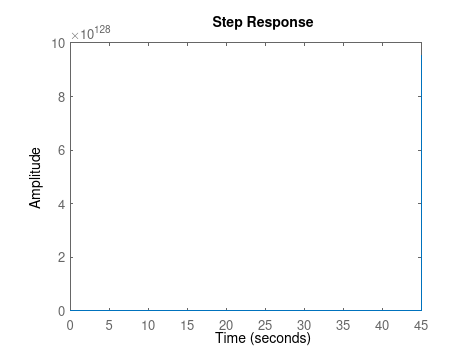

sys = ss(Ps/(1+Ps));

A = [-200 -10^6 0    0;
      1    0    0    0;
      0    1    0    0;
      0    0    1    0];

B = [1 0 0 0]';

C = [0 0 200 10^6];
D = 0;




fSample = 5000;
sys = c2d(ss(Ps),1/fSample);
dstep(A,B,C,D)